# 二、测试模型

### 2.1 加载Yolov2模型

clear;clc;
load YoloModel.mat

### 2.2 读取图像

[file,path] = uigetfile("*.jpg;*.png;*.jpeg");
filepath = fullfile(path,file);

### 2.3 目标检测

if file ~= 0
    img = imread(filepath);
    n = size(img,3);
    I = img ;
    if n == 1
        I(:,:,1) = img;
        I(:,:,2) = img;
        I(:,:,3) = img;
    end
    [bboxes,scores] = detect(detector,I,"Threshold",0.3);%利用训练好Yolov2模型进行检查
end
scores = strcat(string(round(scores,4)*100),"%");
number = string(numel(scores));

### 2.4 输出识别结果

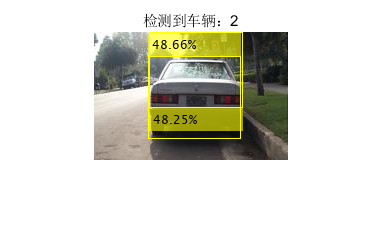

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure,imshow(img),title(strcat("检测到车辆：",number));